# Task 1

table_data = readtable('ContestData.dat.txt');

data = table2array(table_data(:,8));
fignum = 0

fignum = 0

fignum = fignum + 1

fignum = 1

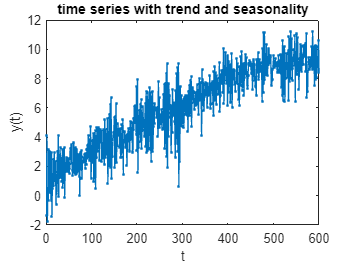

figure(fignum)
clf
plot(data,'.-')
hold on
xlabel('t')
ylabel('y(t)')
title('time series with trend and seasonality')

** task1.a**

%%%%%% 1.a) Remove trend using a moving average filter

maorder = input('Remove trend: Give an order for the moving average filter: > ');
mv = movingaveragesmooth2(data,maorder);
fignum = fignum + 1 

fignum = 2

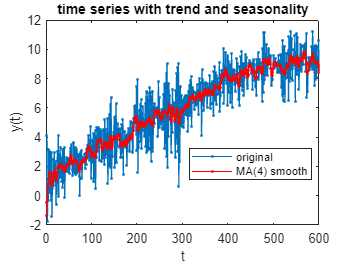

figure(fignum)
clf
plot(data,'.-')
hold on
plot(mv,'.-r')
xlabel('t')
ylabel('y(t)')
title('time series with trend and seasonality')
legend('original',sprintf('MA(%d) smooth',maorder),'Location','Best')


xv = data - mv;
fignum = fignum + 1

fignum = 3

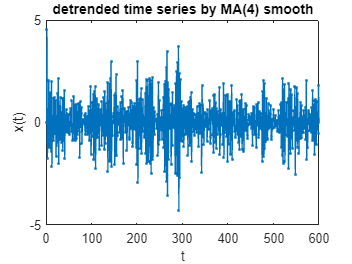

figure(fignum)
clf
plot(xv,'.-')
xlabel('t')
ylabel('x(t)')
title(sprintf('detrended time series by MA(%d) smooth',maorder))

**task 1.b**

% Detrend using the method of first differences
y_diff = diff(data);

% Plot original and detrended time series
fignum = fignum + 1

fignum = 4

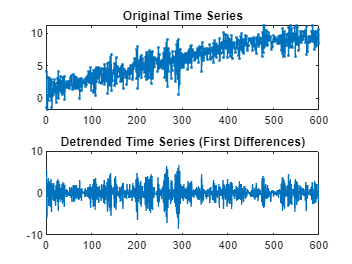


figure(fignum);
subplot(2,1,1);
plot(data,'.-');
title('Original Time Series');

subplot(2,1,2);
plot(y_diff);
title('Detrended Time Series (First Differences)');